close all
clc
disp('Elias Assaf 315284729 - Jameel Nassar 206985152')

## Section 1:

if we look closely at the equation for the fourier transform, we notice that we sum over all m and all n, we can change the order of the summation a little, and give it a matrix form instead of doing it in foor loops, which would take O(M*N) calculations for each cell, and there is M*N cells.

we derive the matrix equations for the fft:

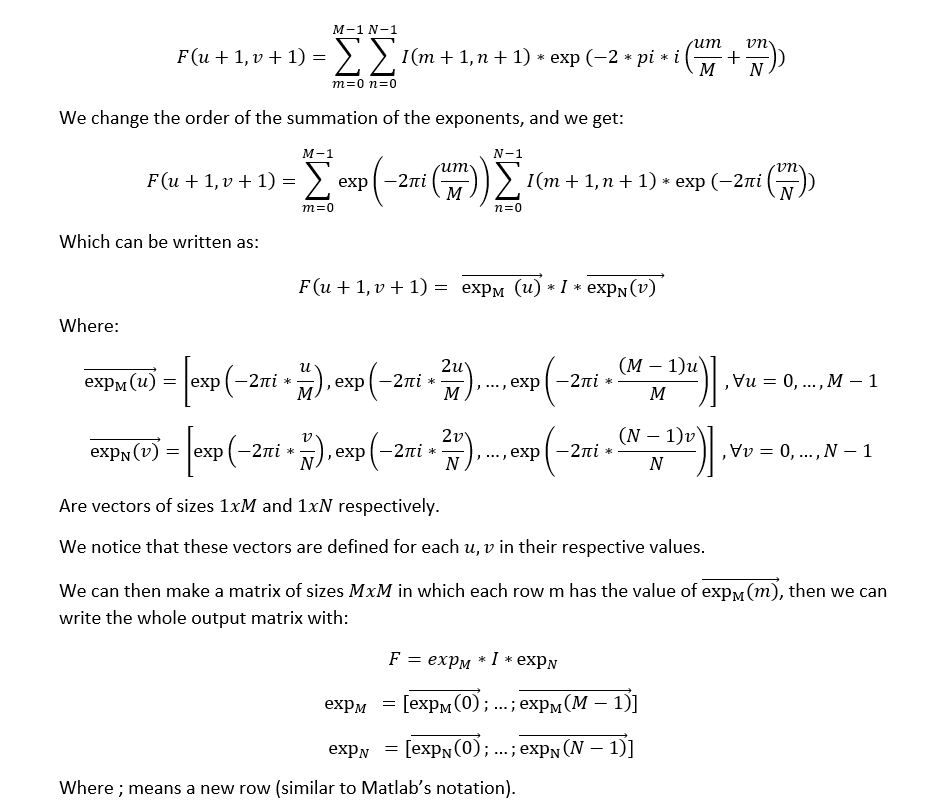

similarly for ifft.

the fftshift is simply dividing the matrix into 4 quadrants and swapping quadrant 1 and 4, 2 and 3.

note that for this to work N,M need to be even numbers.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Section 1.1

beatles = imread("beatles.png");
beatles_norm = double(rgb2gray(beatles))/255;
beatles_fft2 = dip_fft2(beatles_norm);
beatles_fft2_matlab = fft2(beatles_norm);
figure;sgtitle("fft2 of beatles")
subplot(2,2,1);imagesc(log10(abs(dip_ftheftshift(beatles_fft2))));title("our version Amplitude");colorbar;
subplot(2,2,2);imagesc(angle(dip_fftshift(beatles_fft2)));title("phase");colorbar;
subplot(2,2,3);imagesc(log10(abs(dip_fftshift(beatles_fft2_matlab))));title("matlab version Amplitude");colorbar;
subplot(2,2,4);imagesc(angle(dip_fftshift(beatles_fft2_matlab)));title("phase");colorbar;


beatles_ifft2 = dip_ifft2(beatles_fft2);
beatles_ifft2_matlab = ifft2(beatles_fft2_matlab);
figure;sgtitle("ifft2 of beatles")
subplot(2,2,1);imshow(beatles_norm);title("original image");
subplot(2,2,2);imshow(real(beatles_ifft2));title("our ifft");
subplot(2,2,4);imshow(real(beatles_ifft2_matlab));title("matlab ifft");

in the next section we want to free willy.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Section 1.2.1
load("freewilly.mat");
imprisoned_willy = freewilly;
figure;imshow(imprisoned_willy);title("imprisoned willy");

we take a mental exercise where we imagine a sin function on the x axis with the parameters:

sin(2*pi*f_x/N * x), x=0,...,N-1

for f_x=1 we only get 1, for f_x=2 we get 2 cycles and so on...

we count the number of cycles of the black and white bars in the picture and notice the very nice fact that they are a nice even integer number of value 10, which is the f_x we are looking for.

[M,N] = size(imprisoned_willy);
[X_grid, Y_grid] = meshgrid(0:N-1, 0:M-1);
f_x = 10;
prison = 0.5 * sin(2*pi*f_x/N * X_grid);
figure;imshow(prison);title("prison")
%freed_willy = imprisoned_willy - prison;
%figure;imshow(freed_willy);title("freed willy by -");

after building the prison ourselves and using fft on it, we expect to have a "lambda" function on the frequency domain where the peaks exist on ± f_x.

and since we have no signal in the y axis (or DC signal with value 0) we expect its fft to be 0 at all the frequencies.

prison_fft = fft2(prison);
figure;imshow(abs(dip_fftshift(prison_fft)));title("prison fft2")
Free_Willy(imprisoned_willy);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Section 1.2.2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Section 3
beatles = imread("beatles.png");
beatles_norm = double(rgb2gray(beatles))/255;
beatles_dct2 = dct2(beatles_norm);
[M_beatles, N_beatles] = size(beatles_norm);
figure;imagesc(log(abs(beatles_dct2)));colormap(jet(64));colorbar;title('dct of beatles image')

to remove half of the values randomly, we first make a vector of length 1X (M*N), where M,N are the dimentions of the beatles image, where half of it equals 1 and the other half equals 0.

we then use Matlab randperm function to shuffle the elements around (we use it a few times to distribute evenly)

we then reshape it back to size MXN.

since this new matrix is a binary matrix with values 0 and 1, we can multiply index by index to remove half of the values.

half_ones_rand = [ones(1,M_beatles*N_beatles/2) zeros(1,M_beatles*N_beatles/2)];
for i = 1:7 %shuffle few times
    half_ones_rand = half_ones_rand(randperm(length(half_ones_rand))); 
end
half_ones_rand = reshape(half_ones_rand, [M_beatles, N_beatles]);
beatles_dct2_half_rand = half_ones_rand .* beatles_dct2;
beatles_idct2_half_rand = idct2(beatles_dct2_half_rand);
figure;sgtitle("half values removed randomly from dct domain");
subplot(1,2,1);imshow(beatles_norm);title("original image");
subplot(1,2,2);imshow(beatles_idct2_half_rand);title("50% values removed randomly");

for the next section, we need to zero out the half lower absolute values of the dct, for that we remember the definition of median, the value which separates the higher half from the lower half of the data, which means that we can zero out all the values smaller than the median value .

notice that here we only deal in absolutes.

beatles_dct2_half_lowest = beatles_dct2;
beatles_dct2_abs_median = median(abs(beatles_dct2_half_lowest), 'all');
beatles_dct2_half_lowest(beatles_dct2_half_lowest < beatles_dct2_abs_median & beatles_dct2_half_lowest > -beatles_dct2_abs_median) = 0;
beatles_idct2_half_lowest = idct2(beatles_dct2_half_lowest);
figure;sgtitle("half absolute lowest values removed from dct domain (values lower than the median)");
subplot(1,2,1);imshow(beatles_norm);title("original image")
subplot(1,2,2);imshow(beatles_idct2_half_lowest);title("50% lowest values removed")


figure;sgtitle("values from (-a,a) removed from dct domain");
subplot(2,3,1);imshow(beatles_norm);title('original image');
i=2;
for a = [0.02 0.05 0.07 0.09 0.15]
    beatles_dct2_no_a = beatles_dct2;
    beatles_dct2_no_a(beatles_dct2_no_a < a & beatles_dct2_no_a > -a) = 0;
    beatles_idct2_no_a = idct2(beatles_dct2_no_a);
    perc = sum(beatles_dct2_no_a == 0, 'all') / numel(beatles_dct2);
    subplot(2,3,i);imshow(beatles_idct2_no_a);title(['a = ' num2str(a) ', percentage = ' num2str(perc)])
    i = i+1;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% functions

function [img_fft2] = dip_fft2(I)
    [M,N] = size(I);
    M_vec = (0:M-1);
    N_vec = (0:N-1);
    M_mat = exp(-2*pi*1i * (M_vec.' * M_vec)/M);
    N_mat = exp(-2*pi*1i * (N_vec.' * N_vec)/N);
    img_fft2 = M_mat * I * N_mat;
end


function [img_ifft2] = dip_ifft2(F)
    [M,N] = size(F);
    M_vec = (0:M-1);
    N_vec = (0:N-1);
    M_mat = exp(2*pi*1i * M_vec.' * M_vec/M);
    N_mat = exp(2*pi*1i * N_vec.' * N_vec/N);
    img_ifft2 = M_mat * F * N_mat;
    img_ifft2 = img_ifft2/(M*N);
end

function [shifted_fft2] = dip_fftshift(F)
    [M,N] = size(F);
    quad_1 = F(1:M/2,1:N/2);
    quad_2 = F(M/2+1:end, 1:N/2);
    quad_3 = F(M/2+1:end, N/2+1:end);
    quad_4 = F(1:M/2, N/2+1:end);
    shifted_fft2 = [quad_3 quad_2; quad_4 quad_1];
end
function [freed_willy] = Free_Willy(Willy)
    freed_willy = fft2(Willy);
    freed_willy(1, 1+10) = 0;
    freed_willy(1, 1+end-10) = 0;
    freed_willy = real(ifft2(freed_willy));
    figure;imshow(freed_willy);title("freed willy");
end